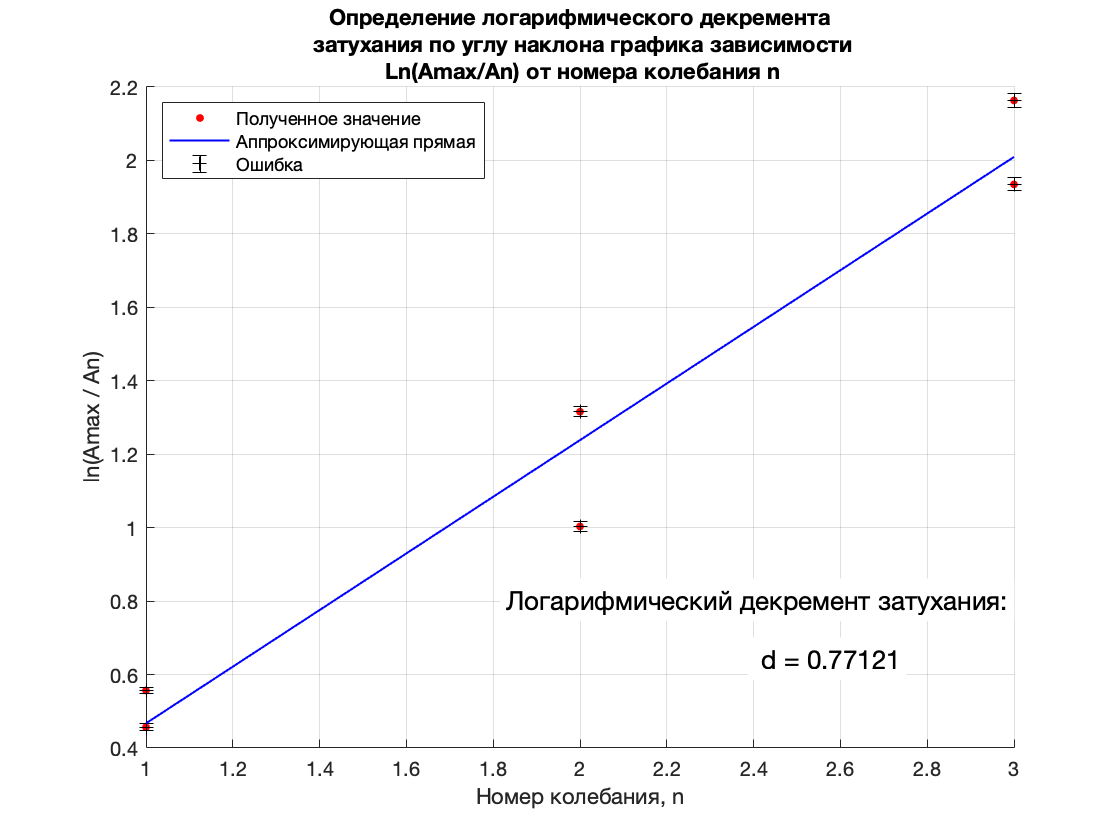

close all;
clear variables;
f1 = figure();
hold all;

Amax = importdata("40cmLaba1.4.3.xlsx");
% Amaxsort = sort([Amax.data(1:8,8)', Amax.data(1:8,16)', Amax.data(1:8,24)'],"ascend")
y1 = Amax.data(1:3,7)';
x1 = 1:1:3;
p1 = plot(x1,y1,"r.","MarkerSize",10);
% appr1 = polyfit(x1,y1,1);
% yAppr1 = polyval(appr1, x1);
% plot(x1,yAppr1,'b',"LineWidth",1);
grid on;

y2 = sort(Amax.data(1:3,15),"ascend");
x2 = 1:1:3;
p2 = plot(x2,y2,"r.","MarkerSize",10);

% y3 = Amax.data(1:7,24)';
% x3 = 1:1:7;
yneg = linspace(0.009,0.018,3);
ypos = yneg;
% p4 = plot(x3,y3,"r.","MarkerSize",10);
errorbar(x1,y1,ypos,yneg,"k+");
p5 = errorbar(x2,y2,ypos,yneg,"k+");
% p5 = errorbar(x3,y3,ypos,yneg,"k+");
Y = sort([Amax.data(1:3,7)', Amax.data(1:3,15)'],"ascend");
X = [1,1,2,2,3,3];
appr2 = polyfit(X,Y,1);
yAppr2 = polyval(appr2, x2);
p3 = plot(x2,yAppr2,'b',"LineWidth",1);
% appr3 = polyfit(x3,y3,1);
% yAppr3 = polyval(appr3, x3);
% plot(x3,yAppr3,'k',"LineWidth",1);
xlabel("Номер колебания, n");
ylabel("ln(Amax / An)");
legend([p1,p3,p5],["Полученное значение","Аппроксимирующая прямая","Ошибка"],"Location","northwest");

d = appr2(:,1);
str = {'Логарифмический декремент затухания:'};
text(max(x2)*0.61, max(yAppr2)* 0.4, str,"FontSize",13,"BackgroundColor","w");
text(max(x2)*0.8, max(yAppr2)* 0.32, [' d = ', num2str(d)],"FontSize",13,"BackgroundColor","w");
title(["Определение логарифмического декремента"," затухания по углу наклона графика зависимости"," Ln(Amax/An) от номера колебания n"]);
saveas(f1,'40cm_Log_d_Laba1_4_3_T_A.png');